**과제1**

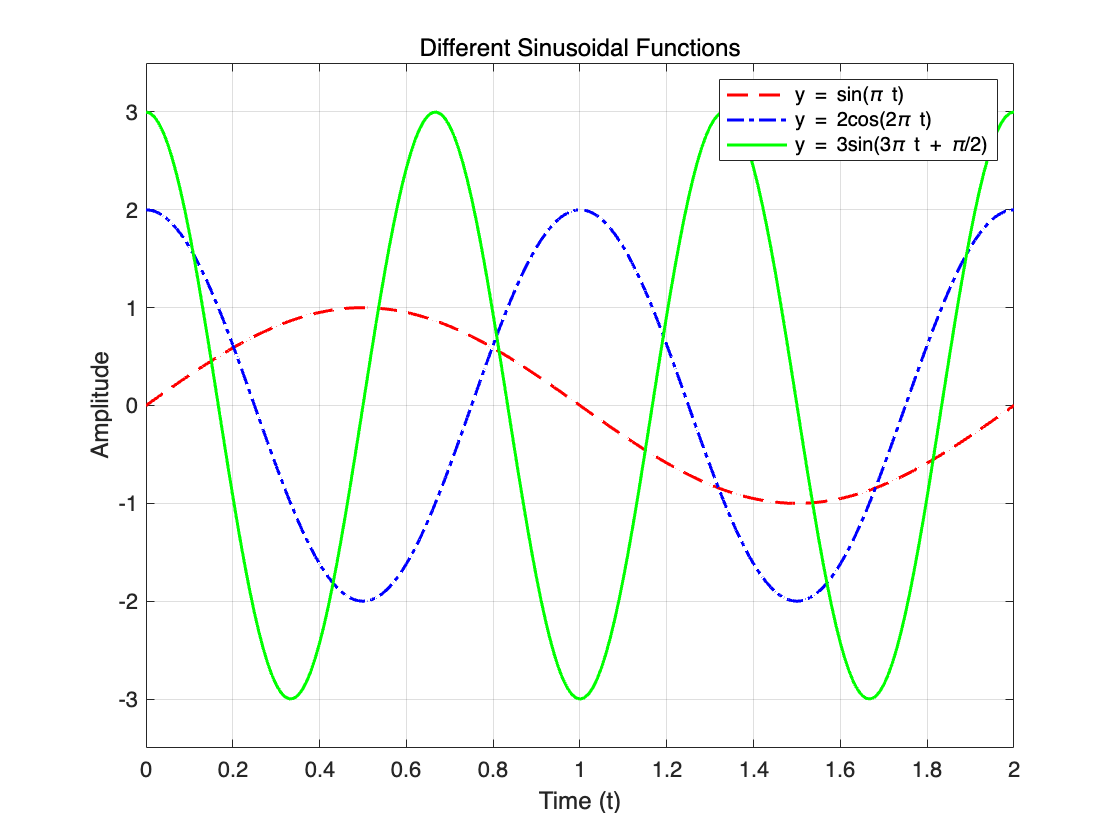

clc; clear; close all;

t = 0:0.01:2;  % 시간축 설정 (0부터 2까지 0.01 간격)
y1 = sin(pi*t);          % y = sin(πt)  
y2 = 2*cos(2*pi*t);      % y = 2cos(2πt)
y3 = 3*sin(3*pi*t + pi/2); % y = 3sin(3πt + π/2)

plot(t, y1, '--r', 'LineWidth', 1.5); hold on;  % 빨간색 점선
plot(t, y2, '-.b', 'LineWidth', 1.5); hold on;  % 파란색 점-점선
plot(t, y3, 'g', 'LineWidth', 1.5);  % 초록색 실선

axis([0 2 -3.5 3.5]);  % x축(0~2)과 y축(-3.5~3.5) 범위 설정
grid on;  % 격자 추가
legend('y = sin(\pi t)', 'y = 2cos(2\pi t)', 'y = 3sin(3\pi t + \pi/2)');  % 범례 추가
title('Different Sinusoidal Functions');  % 그래프 제목 추가
xlabel('Time (t)');  % x축 레이블 추가
ylabel('Amplitude');  % y축 레이블 추가

**과제2**

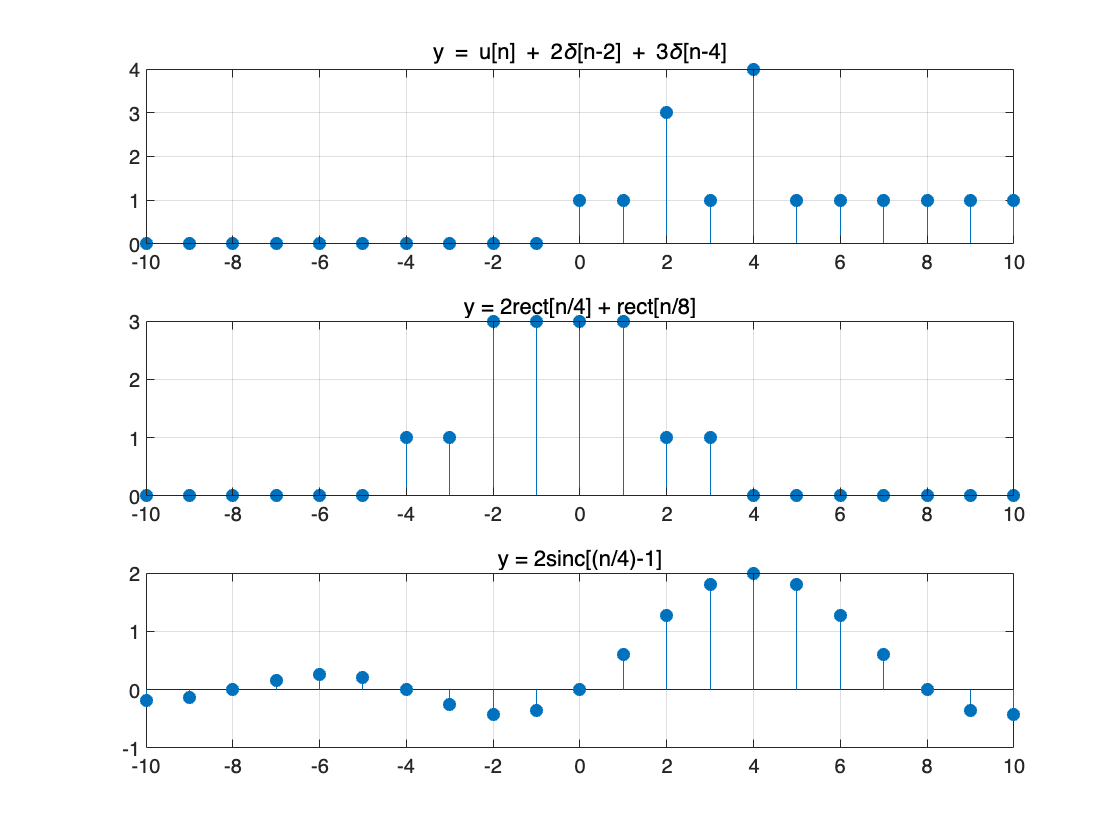

figure;

n = -10:1:10;
unit_function = (n >= 0);  % 단위 계단 함수 u[n]
impulse_2 = (n == 2);  % 델타 함수 δ[n-2]
impulse_4 = (n == 4);  % 델타 함수 δ[n-4]

y1 = unit_function + 2*impulse_2 + 3*impulse_4;  % u[n] + 2δ[n-2] + 3δ[n-4]
y2 = 2*rectpuls(n/4) + rectpuls(n/8); % rectpuls()로 생성
y3 = 2*sinc((n/4) - 1);  % sinc()로 생성

subplot(3,1,1);
stem(n, y1, 'filled'); grid on;
title('y = u[n] + 2\delta[n-2] + 3\delta[n-4]');

subplot(3,1,2);
stem(n, y2, 'filled'); grid on;
title('y = 2rect[n/4] + rect[n/8]');

subplot(3,1,3);
stem(n, y3, 'filled'); grid on;
title('y = 2sinc[(n/4)-1]');

과제3

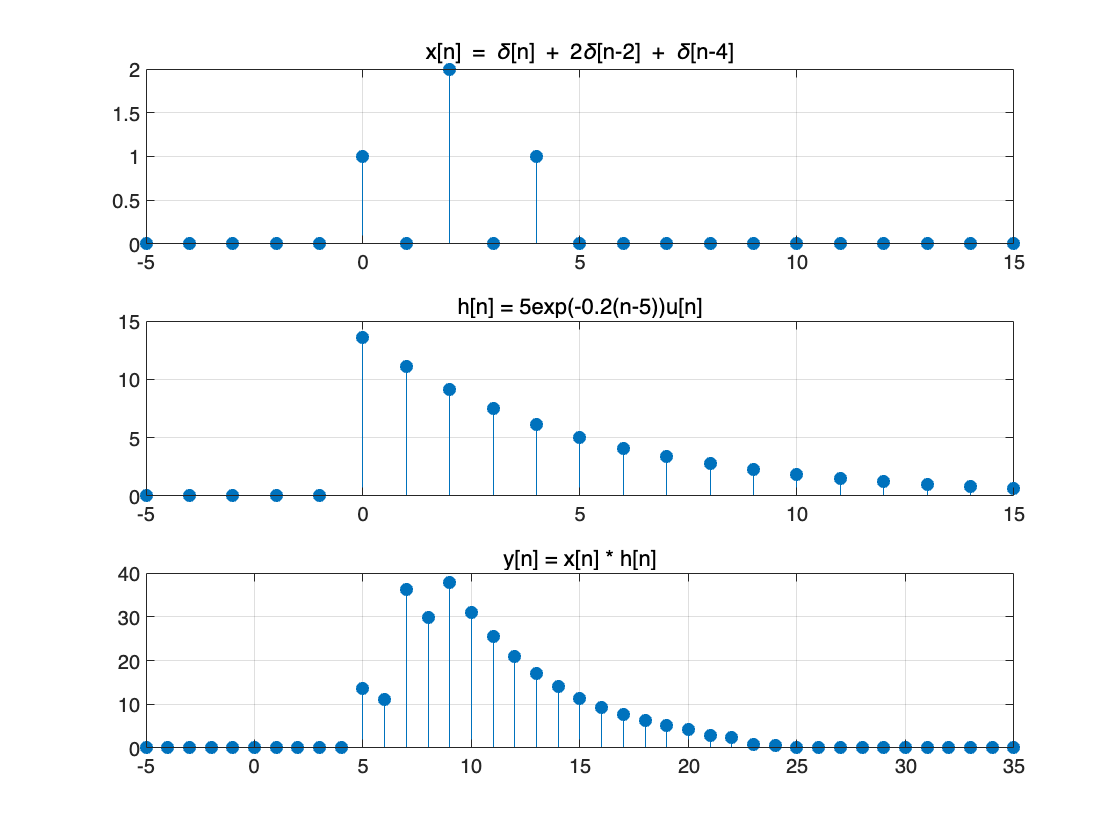

figure;
n = -5:1:15; %n생성
x = (n == 0) + 2*(n == 2) + (n == 4); %x 생성 delta함수 성질 이용
h = 5 * exp(-0.2*(n-5)) .* (n >= 0); %h생성
y = conv(x, h); %컨볼루션 수행

% 컨볼루션 결과의 정확한 x축 범위 설정
n_y = -5:1:(-5 + length(y) - 1);

subplot(3,1,1);
stem(n, x, 'filled'); grid on;
title('x[n] = \delta[n] + 2\delta[n-2] + \delta[n-4]');

subplot(3,1,2);
stem(n, h, 'filled'); grid on;
title('h[n] = 5exp(-0.2(n-5))u[n]');

subplot(3,1,3);
stem(n_y, y, 'filled'); grid on;
title('y[n] = x[n] * h[n]');